[MATLAB | 一行代码生成箭头坐标轴，为坐标轴增添箭头 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247485474&idx=1&sn=50d91e497520e320ccf7e84ab4ffd766&chksm=cf609289f8171b9f14f55d93c19d4659107f78a2bbe655c86ea3a7f8b498fa7ea633aa05b49f&scene=178&cur_album_id=2560715562641768449#rd)

## 基础使用

编写好代码后在最后面引用一下工具函数即可：

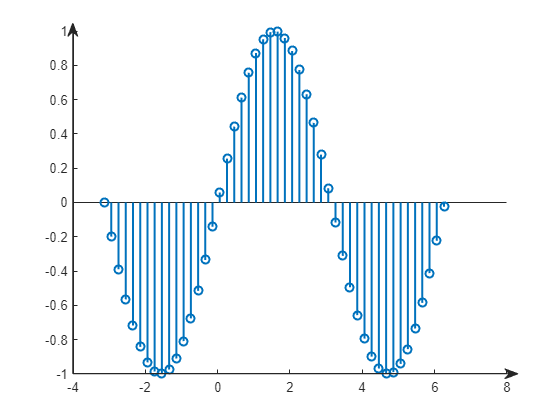

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹




% arrow axes demo1
% @author:slandarer

t=-pi:.2:2*pi;
stem(t,sin(t),'LineWidth',1.5);

arrowAxes()

## 轴方向

可以调整坐标区域的XAxisLocation属性及YAxisLocation属性来调整坐标轴的方向和位置，总共有九种组合，篇幅问题这里不一一列举，想了解的可以去以下网址瞅瞅：

https://ww2.mathworks.cn/help/matlab/ref/matlab.graphics.axis.axes-properties.html?searchHighlight=axes&s_tid=srchtitle_axes_2

这里只列举常用的四种：

clf
% arrow axes demo2
% @author:slandarer

t=-pi:.2:2*pi;


% 子图1
ax1=subplot(2,2,1);
plot(t,sin(t),'LineWidth',1.5);
arrowAxes(ax1)

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹




% 子图2
ax2=subplot(2,2,2);
plot(t,sin(t),'LineWidth',1.5);
ax2.XAxisLocation='top';
ax2.YAxisLocation='right';
arrowAxes(ax2)

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹




% 子图3
ax3=subplot(2,2,3);
plot(t,sin(t),'LineWidth',1.5);
ax3.XAxisLocation='origin';
arrowAxes(ax3)

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹



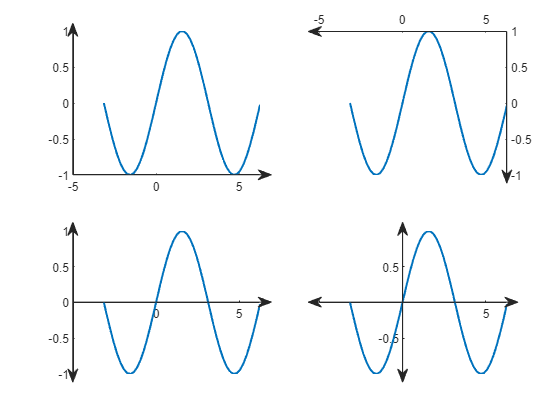

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹




% 子图4
ax4=subplot(2,2,4);
plot(t,sin(t),'LineWidth',1.5);
ax4.XAxisLocation='origin';
ax4.YAxisLocation='origin';
arrowAxes(ax4)

## 轴的其他属性

在引用工具函数前调整坐标轴的粗细和颜色，引用工具函数时，工具函数会自动提取坐标轴的属性并赋予箭头坐标轴：

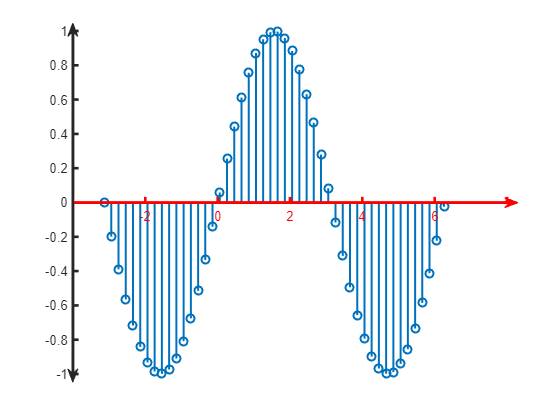

 
  @author: slandarer
  @公众号: slandarer随笔
  @知乎  : hikari
  @CSDN  : slandarer
  
  期待您的关注!!!

    名为 arrowAxes 的文件夹



clf
% arrow axes demo3
% @author:slandarer

t=-pi:.2:2*pi;
stem(t,sin(t),'LineWidth',1.5);

% 修改坐标轴属性
ax=gca;
ax.XColor=[1,0,0];
ax.LineWidth=2;
ax.XAxisLocation='origin';

arrowAxes(ax)

**后言**

不管画多少子图，怎样的轴方向和位置，每个子图都能像如下这样任意调整坐标范围和图像缩放。